# **fitVirus03**

Estimation of coronavirus epidemy size by the logistic model


$$C=\frac{K}{1+Ae^{-\textrm{rt}} }$$


C - number of cases, *t*- time, *K,r*,$A=K/C_0 -1$ are regression parameters.

**WARNING.** **The method does not apply to the early stages of an epidemic. Also, results are useless if regression statistic does not meet minimum criteria, say R2 > 0.8, p-value < 0.05.**

Besides, data and regression parameters report (see below) contains

tau -- epidemy growth phase duration

end - datum of end of the steady-state phase, i.e. transition to ending phase

tpeak -- the epidemy turning point

dCdt -- maximum infection rate

On the epidemy evaluation graph, the epidemy rate is plotted with a blue line. Region colors separate epidemy phases (these are not standard but arbitrarily chosen for convenience):

red - fast growth phase

yellow - transition to steady-state phase

green - ending phase (plateau stage)

**Usage**:

[b] = fitVirus03(@getData)

b -- regression coefficients b(1)=K, b(2)=r, b(3)=A

getData - function which return [country,C,date0]  where 'country' is country name, 'C' is array with daily number of cases, 'data0' is start date. Currently, only data for China, South Korea, Itala and Iran  are available. For other countries, the user must provide his own data function and add it to fitVirus03.

**NOTE**.  **Regression convergence depends significantly on the initial approximation. It may fail for a pure initial guess or for small data set.**

## Example 1

Estimate epidemic final size in China

**** Estimation of epidemy size for China
Regression parameters for complet data set


mdl = Nonlinear regression model:
    y ~ fitVirus03/fun(b,X)

Estimated Coefficients:
          Estimate       SE        tStat       pValue  
          ________    _________    ______    __________

    b1      80772        489.04    165.16    2.0205e-72
    b2    0.22568     0.0062941    35.855    2.4094e-38
    b3     191.23        26.978    7.0882    3.5795e-09


Number of observations: 55, Error degrees of freedom: 52
Root Mean Squared Error: 1.9e+03
R-Squared: 0.997,  Adjusted R-Squared 0.997
F-statistic vs. zero model: 1.61e+04, p-value = 4.02e-77


Evaluation of model parameters for China
 day       date        C        K       r    C0   Tau      end  dCdt tpeak       peak
                 (cases)  (cases) (1/day) (cases) (day)          (c/day) (day)           
  28 12-Feb-2020    59800    70493   0.226   454    88 29-Feb-2020  3989    22 07-Feb-2020
  29 13-Feb-2020    63850    92517   0.198   662    96 04-Mar-2020  4585    24 09-Feb-2020
  30 14-Feb-2020    66492    99502   0.192   717   100 06-Mar-2020  4785    25 10-Feb-2020
  31 15-Feb-2020    68500    96789   0.195   694   100 06-Mar-2020  4712    25 10-Feb-2020
  32 16-Feb-2020    70548    93101   0.199   655    96 04-Mar-2020  4625    24 09-Feb-2020
  33 17-Feb-2020    72436    90221   0.203   618    96 04-Mar-2020  4569    24 09-Feb-2020
  34 18-Feb-2020    74199    88249   0.206   588    96 04-Mar-2020  4540    24 09-Feb-2020
  35 19-Feb-2020    74576    86134   0.210   550    96 04-Mar-2020  4519    24 09-Feb-2020
  36 20-Feb-2020    75464    84630   0.213   521    92

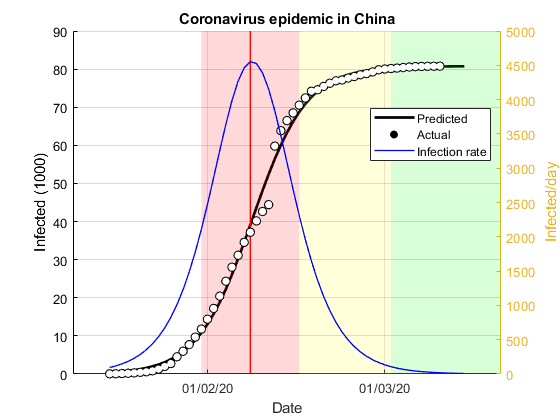


Short-term forecasting for China
 day         date     actual    predict    error % case/day act. case/day pred.     error %
  50  05-Mar-2020      80552      80529      0.029        143         61      57.343
  51  06-Mar-2020      80651      80578      0.091         99         49      50.505
  52  07-Mar-2020      80695      80617      0.097         44         39      11.364
  53  08-Mar-2020      80736      80648      0.109         41         31      24.390
  54  09-Mar-2020      80754      80673      0.100         18         25      38.889
  55  10-Mar-2020      80778      80693      0.105         24         20      16.667
  56  11-Mar-2020          -      80709          -          -         16
  57  12-Mar-2020          -      80722          -          -         13
  58  13-Mar-2020          -      80732          -          -         10
  59  14-Mar-2020          -      80740          -          -          8
  60  15-Mar-2020          -      80746          -          -          6

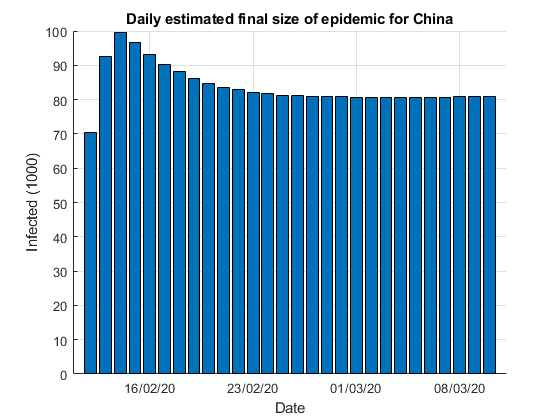

fitVirus03(@getDataChina);

## Example 2

Estimate epidemic final size in South Korea

**** Estimation of epidemy size for South Korea
Regression parameters for complet data set


mdl = Nonlinear regression model:
    y ~ fitVirus03/fun(b,X)

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    b1     7883.6       100.24    78.644    2.3728e-25
    b2    0.37927     0.012001    31.602      6.86e-18
    b3     96.863       11.883    8.1513    1.2674e-07


Number of observations: 22, Error degrees of freedom: 19
Root Mean Squared Error: 125
R-Squared: 0.998,  Adjusted R-Squared 0.998
F-statistic vs. zero model: 9.23e+03, p-value = 3.18e-30


Evaluation of model parameters for South Korea
 day       date        C        K       r    C0   Tau      end  dCdt tpeak       peak
                 (cases)  (cases) (1/day) (cases) (day)          (c/day) (day)           
  11 28-Feb-2020     2337     7021   0.363    90    44 11-Mar-2020   636    11 29-Feb-2020
  12 29-Feb-2020     3150    17147   0.328   102    60 19-Mar-2020  1406    15 04-Mar-2020
  13 01-Mar-2020     4212    36973   0.313   109    72 25-Mar-2020  2895    18 07-Mar-2020
  14 02-Mar-2020     4812    10186   0.363    84    52 15-Mar-2020   923    13 02-Mar-2020
  15 03-Mar-2020     5328     7833   0.398    67    44 11-Mar-2020   779    11 29-Feb-2020
  16 04-Mar-2020     5766     7224   0.418    58    44 11-Mar-2020   754    11 29-Feb-2020
  17 05-Mar-2020     6284     7248   0.417    58    44 11-Mar-2020   755    11 29-Feb-2020
  18 06-Mar-2020     6767     7447   0.406    64    44 11-Mar-2020   756    11 29-Feb-2020
  19 07-Mar-2020     7134     7632   0.396    69

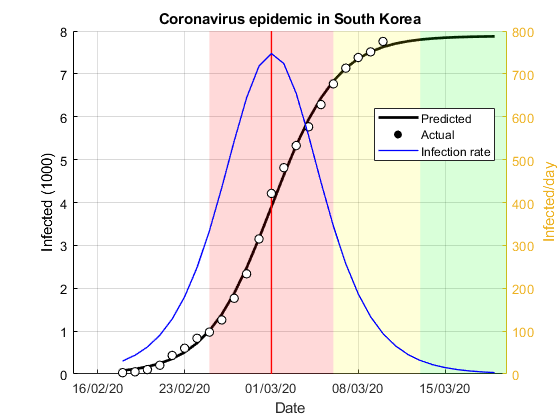


Short-term forecasting for South Korea
 day         date     actual    predict    error % case/day act. case/day pred.     error %
  17  05-Mar-2020       6284       6440      2.482        518        502       3.089
  18  06-Mar-2020       6767       6835      1.005        483        395      18.219
  19  07-Mar-2020       7134       7134      0.000        367        299      18.529
  20  08-Mar-2020       7382       7355      0.366        248        221      10.887
  21  09-Mar-2020       7513       7514      0.013        131        159      21.374
  22  10-Mar-2020       7755       7627      1.651        242        113      53.306
  23  11-Mar-2020          -       7706          -          -         79
  24  12-Mar-2020          -       7761          -          -         55
  25  13-Mar-2020          -       7799          -          -         38
  26  14-Mar-2020          -       7826          -          -         27
  27  15-Mar-2020          -       7844          -          -     

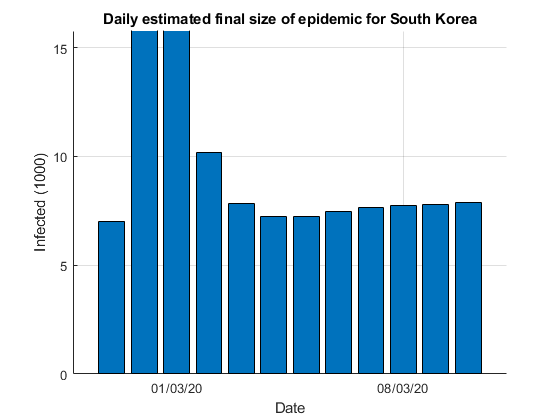

fitVirus03(@getDataSouthKorea);

## Example 3

Estimate epidemic final size in Italy

**** Estimation of epidemy size for Italy
Regression parameters for complet data set


mdl = Nonlinear regression model:
    y ~ fitVirus03/fun(b,X)

Estimated Coefficients:
          Estimate       SE       tStat       pValue  
          ________    ________    ______    __________

    b1      23859       3666.5    6.5074    9.9025e-06
    b2    0.27298     0.013727    19.886    3.4272e-12
    b3     135.22       11.323    11.941    4.6214e-09


Number of observations: 18, Error degrees of freedom: 15
Root Mean Squared Error: 159
R-Squared: 0.998,  Adjusted R-Squared 0.998
F-statistic vs. zero model: 4.46e+03, p-value = 2.39e-22


Evaluation of model parameters for Italy
 day       date        C        K       r    C0   Tau      end  dCdt tpeak       peak
                 (cases)  (cases) (1/day) (cases) (day)          (c/day) (day)           
   9 01-Mar-2020     1694   425229   0.334   115    96 10-Apr-2020 35495    24 17-Mar-2020
  10 02-Mar-2020     2036     4970   0.394    99    36 11-Mar-2020   490     9 02-Mar-2020
  11 03-Mar-2020     2502     4574   0.403    96    36 11-Mar-2020   461     9 02-Mar-2020
  12 04-Mar-2020     3089     5399   0.381   105    40 13-Mar-2020   514    10 03-Mar-2020
  13 05-Mar-2020     3858     7463   0.343   124    44 15-Mar-2020   639    11 04-Mar-2020
  14 06-Mar-2020     4636     8999   0.325   135    48 17-Mar-2020   730    12 05-Mar-2020
  15 07-Mar-2020     5883    15152   0.287   166    60 23-Mar-2020  1086    15 08-Mar-2020
  16 08-Mar-2020     7382    28838   0.261   193    76 31-Mar-2020  1881    19 12-Mar-2020
  17 09-Mar-2020     9172    49201   0.248   209    84

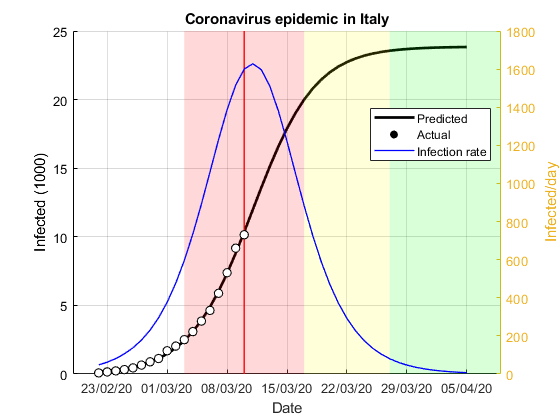


Short-term forecasting for Italy


 day         date     actual    predict    error % case/day act. case/day pred.     error %
  13  05-Mar-2020       3858       3905      1.218        769        812       5.592
  14  06-Mar-2020       4636       4880      5.263        778        975      25.321
  15  07-Mar-2020       5883       6025      2.414       1247       1145       8.180
  16  08-Mar-2020       7382       7335      0.637       1499       1310      12.608
  17  09-Mar-2020       9172       8789      4.176       1790       1454      18.771
  18  10-Mar-2020      10149      10351      1.990        977       1562      59.877
  19  11-Mar-2020          -      11970          -          -       1619
  20  12-Mar-2020          -      13588          -          -       1618
  21  13-Mar-2020          -      15145          -          -       1557
  22  14-Mar-2020          -      16593          -          -       1448
  23  15-Mar-2020          -      17895          -          -       1302
  24  16-Mar-2020          -    

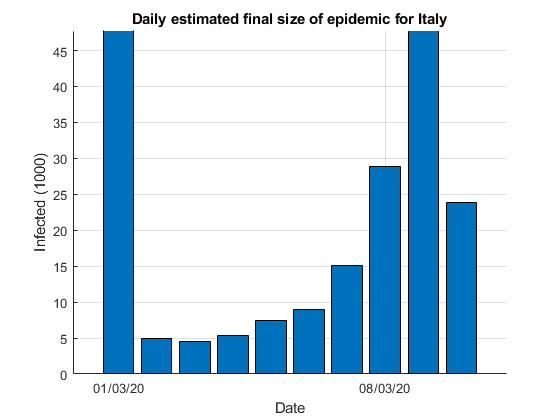

fitVirus03(@getDataItaly);